## Lab 5, Part 1: Deep Q-learning

### 1.1 Introduction

- The objective of this laboratory is to learn about the deep reinforcement learning algorithm Deep Q-learning 

- For related background reading to this lab, you can check the Lecture 13 notes/slides on Blackboard and the paper Mnih, V., Kavukcuoglu, K., Silver, D., Rusu, A. A., Veness, J., Bellemare, M. G., ... & Hassabis, D. (2015). [Human-level control through deep reinforcement learning](https://www.nature.com/articles/nature14236/). Nature, 518(7540), 529-533.

- You will need the Reinforcement Learning Toolbox and the Deep Learning Toolbox installed.

### 1.2 Problem description

The deep reinforcement learning algorithm will be applied to the cart-pole problem in this part (Fig. 1).

- The control objective is to balance the pole, i.e. set the angle $\theta \;$ between the pole and vertical axis to zero. The input to the system is the lateral force, $F$, which is used to push the cart sideways in the +/-   direction. This is a challenging problem to solve due to the nonlinear dynamics.

- To solve the cart-pole problem using deep reinforcement learning with function approximation the state-space will be continuous and the action space will be discrete.

- The action space is defined here as two force values, $a_1 =-10$ and $a_2 =10$. 

- The reward is defined as +1 at each time step for not falling and -10 for falling (it is a discrete reward).                                

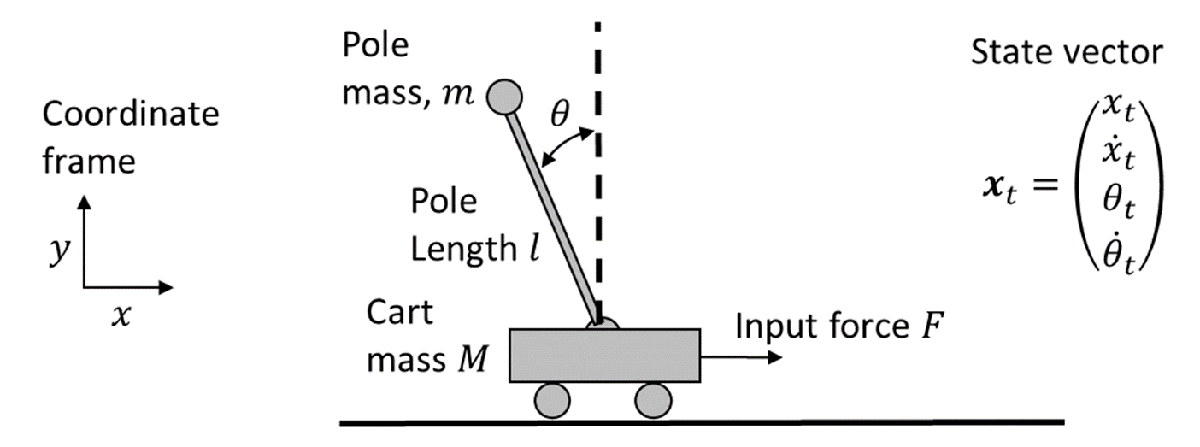

Figure 1. Illustration of the cart-pole balancing problem.                 

### 1.3 Methods

**1.3.1 Data**

In this reinforcement learning problem the data is based on the agents taking actions in an environment from a given state, and receiving rewards, i.e. 

- the input action an agent takes at a time step, $A_t$, 

- the corresponding output state, $S_{t+1}$, and reward, $R_{t+1}$, emitted from the system  

**1.3.2 Model**

In deep Q-learning we are trying to model the optimal action-value function, using a deep learning model, where the action-value function (sum of expected future reward) is defined as


$$    q_{\pi}(s,a) = E\left\lbrack G_{t} | S_{t} = s,A_{t} = a \right\rbrack = E\left\lbrack \sum_{k = 0}^{\infty}{\gamma^{k}R_{t + k + 1} | S_{t} = s,A_{t} = a} \right\rbrack$$


and the optimal action value function is defined as


$$ q_{*}(s,a) = \max_{\pi}q_{\pi}(s,a)$$


and the deep learning model, $\hat{q}(s,a;\theta) $, is used to approximate the optimal action value function,


$$\hat{q}(s,a; \mathbf{\theta}) \approx q_{*}(s,a) $$


**1.3.3 Objective function**

We are trying to obtain an optimal policy, $\pi_{*}(s) $, that maximises expected future reward,


$$\pi_{*}(s) = \arg\max_{a}q_{*}(s,a)$$


To do this we estimate the optimal action value function using the squared error loss function 


$$ L(\mathbf{\theta}) = E \left[ \left( R_{t + 1} + \gamma\max_{a}\hat{q}(S_{t+1},a;\mathbf{\theta}^{-}) - \hat{q}(S_t, A_t;\mathbf{\theta}) \right)^2  \right] $$


where $\hat{q}(S_{t+1},a;\mathbf{\theta}^{-})$ is the target network.

**1.3.4 Estimation algorithm**

The deep Q-learning algorithm is based on Q-learning but does not have its good convergence guarantees and is prone to instability. To overcome this problem, the algorithm uses a few tricks to improve stability, such as defining the target value based on a target network, parameterised by $\mathbf{\theta}^{-}$, and an experience replay buffer where minibatch training samples are drawn widely across the agent's experiences.

Looping over epsiodes and time-steps:

- The agent selects an action to take using the $\epsilon$-greedy method, which trades-off exploration of the environment with exploitation of optimal actions:

                The action is taken at random with probability $\epsilon$,

                    
$$    \pi\left( a | s \right) = A_{t} = a_{j},j \in U\left( 1,n_{a} \right) $$


                else the action is the best action according to the current model of the action value function,

                    
$$ \pi\left( a | s \right) = A_{t} =  \max_{a}Q(s,a)$$
  

- The action is used to explore the environment returing a new state $S_{t+1}$ and reward $R_{t+1}$

- The experience $S_t, A_t, R_{t+1}, S_{t+1}$ is stored in a replay buffer $\mathcal{D}$

- Mini-batches of experience $S_j, A_j, R_{j+1}, S_{j+1}$ are sampled from the replay buffer

- The target $y_t$ is set to $y_t = R_{t+1}$ if the episode terminates, else $y_t =   R_{t + 1} + \gamma\max_{a}\hat{q}(S_{t+1},a;\mathbf{\theta}^{-})$

- One step of gradient descent is taken on the loss $ L(\mathbf{\theta}) = E \left[ \left( y_t - \hat{q}(S_t , A_t;\mathbf{\theta}) \right)^2  \right] $

- Every $C$ steps the target network is updated as $\mathbf{\theta}^{-} = \mathbf{\theta}$

This summarises the deep Q-learning algorithm.

### 1.4 Environment definition

We use the inbuilt Matlab cart pole environment here:

clear all

% Fix the random generator seed for reproducibility
rng(1,'twister');

%% cart pole with with state and action inputs
 
% load predefined environment
env = rlPredefinedEnv("CartPole-Discrete");
 
% get observation and specification info
stateInfo = getObservationInfo(env);      % get state info for cart pole demo
stateDimension = stateInfo.Dimension;     % get continuous state dimension
actionInfo = getActionInfo(env);          % get action info for cart pole demo
numActions = length(actionInfo.Elements); % number of discrete actions
 

### 1.5  Q-function model definition

We define the Q-function as a fully connected network with 10 hidden units and a linear output layer, with the number of outputs corresponding to the number of actions.        

%% Define a Q-function network with state-only input (known in Matlab as a critic)
  
% Create a shallow neural network to approximate the Q-value function 
net = [imageInputLayer(stateDimension,'Normalization','none','Name','myobs') 
       fullyConnectedLayer(10)
       reluLayer
       fullyConnectedLayer(numActions)];
 
% Create the critic using the network 
critic = rlQValueRepresentation(net,stateInfo,actionInfo,'Observation',{'myobs'});

### 1.6 Define the agent options and the training options and train

Define the agent options. These options can be critical because they contain the hyperparameters that affect training stability including the 

update frequency of the target network ('TargetUpdateFrequency') and the experience replay buffer length ('ExperienceBufferLength'). The minibatch size as usual also affects the update because larger minibatch sizes improve the loss function gradient estimate.

You can try changing the parameters to e.g. TargetUpdateFrequency=2, ExperienceBufferLength=2000, MiniBatchSize=32, and see what happens to the learning - you will likely see that learning becomes erratic and not well behaved - try adjusting these hyperparameters individually to understand which parameters or parameter combinations are causing the most problem.

%% Specify agent options, and create an agent using the environment and critic definition
% agent options
agentOpts = rlDQNAgentOptions(...
    'UseDoubleDQN',false, ...    
    'TargetUpdateMethod',"periodic", ...
    'TargetUpdateFrequency',100, ...   
    'NumStepsToLookAhead', 1, ...
    'ExperienceBufferLength',3000, ...
    'DiscountFactor',0.95, ...
    'MiniBatchSize',32);

% Epsilon greedy probability threshold for agent to randomly select an action 
opt.EpsilonGreedyExploration.Epsilon = 0.9;
 
% define the agent
agent = rlDQNAgent(critic,agentOpts);

Define the training options and train the agent:

%% Train the agent
 
% specify reinforcement learning training options
trainOpts = rlTrainingOptions(...
'MaxEpisodes', 100, ...
'MaxStepsPerEpisode', 300, ...
'Verbose', false, ...
'Plots','training-progress',...
'StopTrainingCriteria','AverageReward',...
'StopTrainingValue',200);
 
% train the agent
trainingStats = train(agent,env,trainOpts);

### 1.7 Simulate the trained agent

Simulate the trained agent to examine its performance:

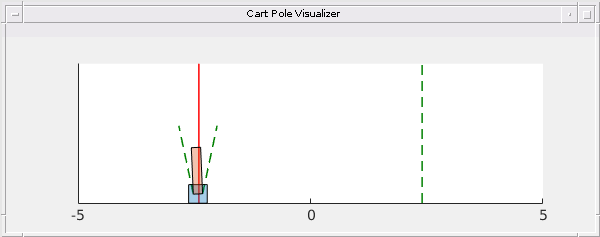

%% Simulate
% Fix the random generator seed for reproducibility
rng(1,'twister');
 
plot(env) % visualise the cart-pole system
simOptions = rlSimulationOptions('MaxSteps',300); % simulation options
experience = sim(env,agent,simOptions);           % log experience

totalReward = sum(experience.Reward)              % extract reward

totalReward = 271

% the end of lab part